# Project 1: Numerical ODEs

Ellie Suit and Ethan Tyler

## Problem 1


$$\frac{\textrm{dy}}{\textrm{dt}}=-2{\;t\;y}^2 ,y\left(0\right)=1$$


**(a)**

One can solve the above IVP using separation of variables, since the equation is separable. This can be seen by setting $p(t) = -2t$ and $q(y) = y^2$. It then takes on the form $dy/dt = p(t)q(y)$ and we can solve it using separation of variables. First we can rewrite it as


$$\frac{\textrm{dy}}{y^2 }=-2t\;\textrm{dt}$$


and integrating both sides with respect to the corresponding variable ($y$ or $t$) yields 

$-\frac{1}{y}=-\frac{2t^2 }{2}+C$. 

Solving the equation for $y$ thus yields 

$y=\frac{1}{t^2 +c}$. 

This is the general solution for the IVP, where $c$ is an arbituary constant dependent on the initial value. Plugging in $y(0) = 1$, we find that $c = -1$ and therefore


$$y=\frac{1}{t^2 +1}$$


is the solution to the IVP. 

**(b)**

Euler's method is a numerical approximation that uses discrete points to approximate a continuous curve. It is useful when we have a differential equation that we cannot solve exactly and must approximate the solution. It takes on the form

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h*f\left(t_n ,\hat{y} {\;}_n \right)$, 

where $\hat{y}_{n}$ and $\hat{y}_{n+1}$ are the approximations of the $y$ values for grid points $n$ and $n+1$ respectfully, $h$ is the spacing between grid points, and $f$ is the derivative with respect to independent variable $t$ of a function $y$. Specifically for the purposes of this problem, the Euler approximation is 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h*\left(-2{t_n {\hat{y} }_n }^2 \right)$.

Therefore,

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n -2\;{h\;t}_n \hat{y} {\;}_n^2$. 

**(c)**

The improved Euler's method is a numerical approximation that aims to reduce much of the error caused by the use of the tangent line in the Euler method. Namely, the Euler method uses only one point to determine the corresponding tangent line and hence the approximation of the location of the next point on the curve, whereas the improved Euler's method takes into account the slopes at each ends of a given time interval of length $h$ and determines the tangent line based on the average of these slopes. The result, using two points instead of one, is more effective and gives a better approximation for the location of the next point on the curve. 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h\;\left\lbrack \frac{f\left(t_n ,\hat{y} {\;}_n \right)+f\left(t_n +h,k_n \right)}{2}\right\rbrack$, 

where $k_n = \hat{y}_n + h f(t_n, \hat{y}_n)$. 

Therefore, for this specific problem, the improved Euler appears as 


$$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h\;\left\lbrack \frac{-2t_n {\hat{y} }_n^2 -2\;\left(t_n +h\right)\left(\hat{y} {\;}_n +h*\left(-2t_n {\hat{y} }_n^2 \right)\right)}{2}\right\rbrack$$


**(d)**

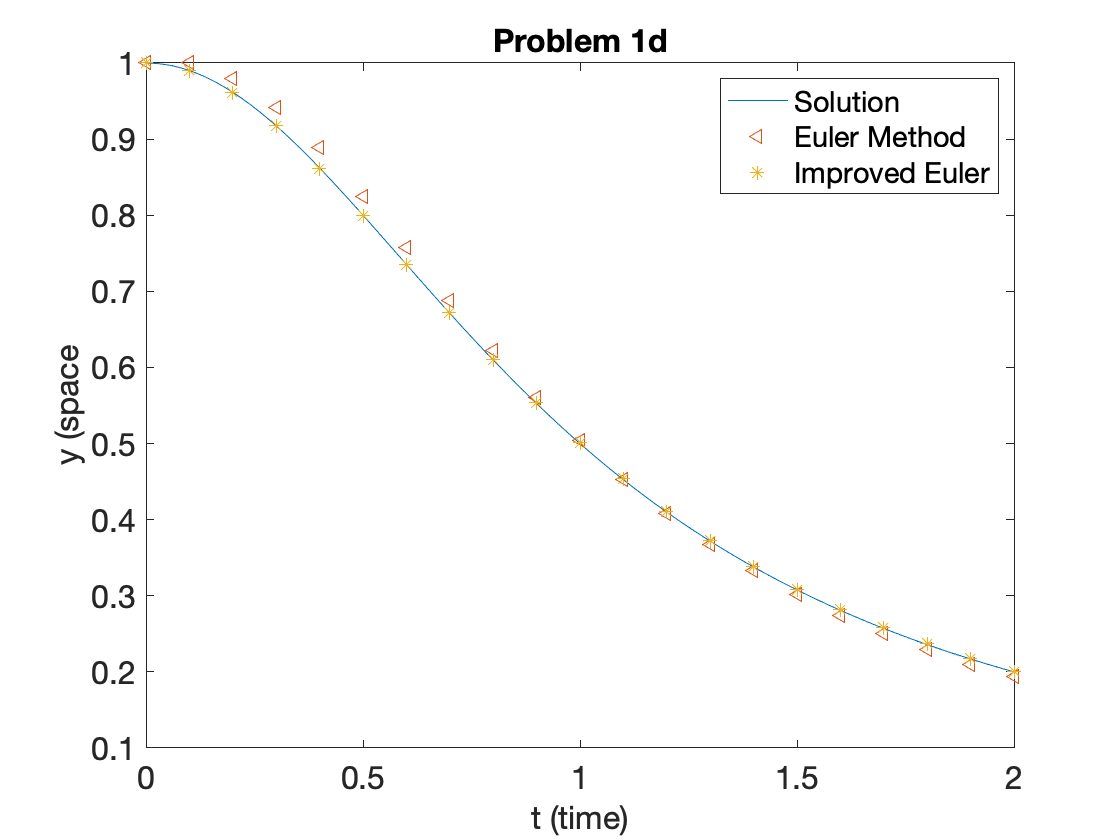

% code goes here
f = @(t, y) -2.*t.*y.^2;
soln1 = @(t) 1./(t.^2 + 1); 
t = linspace(0,2) ;
h = 0.1;

[t_arr, y_arr] = myEuler(1, 0, f, 2/h, h); 
[t_arr_imp, y_arr_imp] = myImprovedEuler(1, f, 2/h, h);


figure
plot(t, soln1(t))
hold on
scatter(t_arr, y_arr, "Marker","<")
scatter(t_arr_imp, y_arr_imp, "Marker","*")
legend("Solution", "Euler Method", "Improved Euler")
xlabel("t (time)", "FontSize",16)
ylabel("y (space", "FontSize", 16)
title("Problem 1d", "FontSize", 16)

The Euler method seems to be noticeably inaccurate towards the beginning and end portions of the range. The improved Euler method sticks to the solution much better than the Euler method. 

**(e) **(f) calculating the error: $E_n =\max \left|\;y\left(t_n \right)\;\;-y_n \right|$

% code goes here 
true_sol = soln1(linspace(0,2,2/h+1));
euler_err = abs(true_sol - y_arr.'); 

max_euler = max(euler_err);
max_euler

max_euler = 0.0263


imp_euler_err = abs(true_sol - y_arr_imp.'); 

max_improved = max(imp_euler_err);
max_improved

max_improved = 0.0010

As calculated above, the global error for the Euler method is 0.0263, whereas the global error for the improved Euler method is 0.001. This behavior is consistent with the observations noted in part (d), where the improved Euler method is more accurate than the Euler method.

**(f)**

 Rate of convergence found using $p\approx \log_2 \left(\frac{E_n \left(h\right)}{E_{2n} \left(\frac{h}{2}\right)}\right)$

% code goes here 
h2 = h/2;
true_sol2 = soln1(linspace(0,2,2/h2+1));
 
[t_arr2, y_arr2] = myEuler(1, 0, f, 2/h2, h2); 
[t_arr_imp2, y_arr_imp2] = myImprovedEuler(1, f, 2/h2, h2);

euler_err = abs(true_sol2 - y_arr2.');
max_euler2 = max(euler_err);
conv_euler = log2(max_euler/max_euler2)

conv_euler = 1.0688

The order of convergence is 1.0688 for the Euler method. 

euler_err_imp = abs(true_sol2 - y_arr_imp2.');
max_euler2_imp = max(euler_err_imp);

conv_euler_imp = log2(max_improved/max_euler2_imp)

conv_euler_imp = 2.0073

The order of convergence is 2.0073 for the improved Euler method. 

**(g)**

% code goes here 
f = @(t, y) -2.*t.*y.^2;
soln1 = @(t) 1./(t.^2 + 1); 
h1 = 0.1;
error = @(sol, arr) max(abs(sol - arr.')); 
h = [h1 h1/2 h1/4 h1/8 h1/16 h1/32 h1/64];

[t,arr1] = myEuler(1, 0, f, 2/h(1), h(1));
[t,arr2] = myEuler(1, 0, f, 2/h(2), h(2));
[t,arr3] = myEuler(1, 0, f, 2/h(3), h(3));
[t,arr4] = myEuler(1, 0, f, 2/h(4), h(4));
[t,arr5] = myEuler(1, 0, f, 2/h(5), h(5));
[t,arr6] = myEuler(1, 0, f, 2/h(6), h(6));
[t,arr7] = myEuler(1, 0, f, 2/h(7), h(7));

s1 = soln1(linspace(0,2,2/h(1)+1));
s2 = soln1(linspace(0,2,2/h(2)+1));
s3 = soln1(linspace(0,2,2/h(3)+1));
s4 = soln1(linspace(0,2,2/h(4)+1));
s5 = soln1(linspace(0,2,2/h(5)+1));
s6 = soln1(linspace(0,2,2/h(6)+1));
s7 = soln1(linspace(0,2,2/h(7)+1));

conv1 = log2(error(s1, arr1)/error(s2, arr2));

conv1 = 1.0688

conv2 = log2(error(s2, arr2)/error(s3, arr3));

conv2 = 1.0343

conv3 = log2(error(s3, arr3)/error(s4, arr4));

conv3 = 1.0171

conv4 = log2(error(s4, arr4)/error(s5, arr5));

conv4 = 1.0085

conv5 = log2(error(s5, arr5)/error(s6, arr6));

conv5 = 1.0043

conv6 = log2(error(s6, arr6)/error(s7, arr7));

conv6 = 1.0021

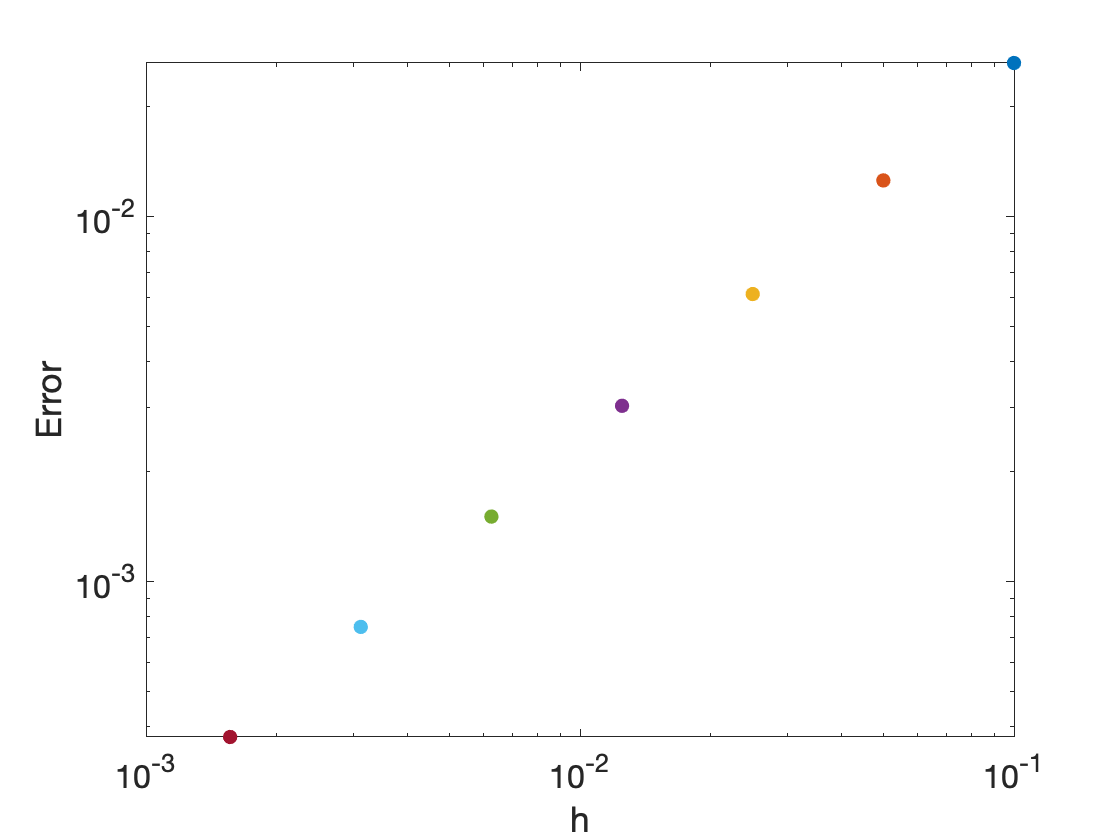


figure
loglog(h(1), error(s1, arr1),"MarkerSize", 20, "Marker",".")
hold on 
loglog(h(2), error(s2, arr2),"MarkerSize", 20, "Marker",".")
loglog(h(3), error(s3, arr3),"MarkerSize", 20, "Marker",".")
loglog(h(4), error(s4, arr4),"MarkerSize", 20, "Marker",".")
loglog(h(5), error(s5, arr5),"MarkerSize", 20, "Marker",".")
loglog(h(6), error(s6, arr6),"MarkerSize", 20, "Marker",".")
loglog(h(7), error(s7, arr7),"MarkerSize", 20, "Marker",".")


xlabel("h", "FontSize",16)
ylabel("Error", "FontSize",16)

As shown in the calculations above the order of convergence between consecutive step sizes is $p = 1$. We also find that the slope of the line is $m = 1$. 

Therefore, $\log(E) = p\log(h) + C$

$\log(E) = \log(h^p) + C$. 

This demonstrates that $E \propto h^p$. This makes sense because as we decrease $h$ by a factor of $2$ the associated error halves (since $log_2(E_n/E_{2n}) = 1$, necesitating that $E_n = 2E_{2n{$. This pattern continues demonstrating that the error is proportional to $h^p$. Therefore $p$ appears as the slope, which is consistent with the above plot. 

slope = (log2(error(s1, arr1)) - log2(error(s7, arr7)))/(log2(h(1))-log2(h(7)))

slope = 1.0225

f = @(t, y) -2.*t.*y.^2;
soln1 = @(t) 1./(t.^2 + 1); 
h1 = 0.1;
error = @(sol, arr) max(abs(sol - arr.')); 
h = [h1 h1/2 h1/4 h1/8 h1/16 h1/32 h1/64];

[t,arr1] = myImprovedEuler(1, f, 2/h(1), h(1));
[t,arr2] = myImprovedEuler(1, f, 2/h(2), h(2));
[t,arr3] = myImprovedEuler(1, f, 2/h(3), h(3));
[t,arr4] = myImprovedEuler(1, f, 2/h(4), h(4));
[t,arr5] = myImprovedEuler(1, f, 2/h(5), h(5));
[t,arr6] = myImprovedEuler(1, f, 2/h(6), h(6));
[t,arr7] = myImprovedEuler(1, f, 2/h(7), h(7));

conv1 = log2(error(s1, arr1)/error(s2, arr2));

conv1 = 2.0073

conv2 = log2(error(s2, arr2)/error(s3, arr3));

conv2 = 2.0039

conv3 = log2(error(s3, arr3)/error(s4, arr4));

conv3 = 2.0021

conv4 = log2(error(s4, arr4)/error(s5, arr5));

conv4 = 2.0010

conv5 = log2(error(s5, arr5)/error(s6, arr6));

conv5 = 2.0005

conv6 = log2(error(s6, arr6)/error(s7, arr7));

conv6 = 2.0002

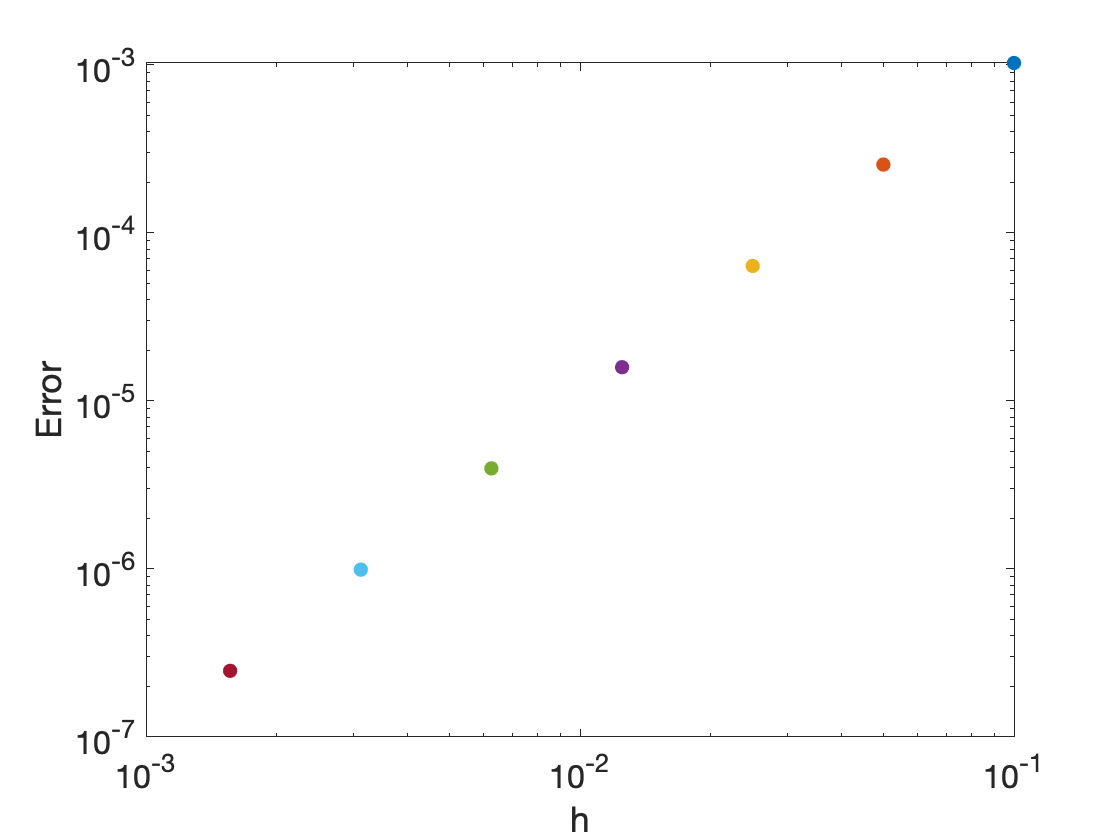


figure
loglog(h(1), error(s1, arr1),"MarkerSize", 20, "Marker",".")
hold on 
loglog(h(2), error(s2, arr2),"MarkerSize", 20, "Marker",".")
loglog(h(3), error(s3, arr3),"MarkerSize", 20, "Marker",".")
loglog(h(4), error(s4, arr4),"MarkerSize", 20, "Marker",".")
loglog(h(5), error(s5, arr5),"MarkerSize", 20, "Marker",".")
loglog(h(6), error(s6, arr6),"MarkerSize", 20, "Marker",".")
loglog(h(7), error(s7, arr7),"MarkerSize", 20, "Marker",".")

xlabel("h", "FontSize",16)
ylabel("Error", "FontSize",16)

slope = (log2(error(s1, arr1)) - log2(error(s7, arr7)))/(log2(h(1))-log2(h(7)))

slope = 2.0025

As shown in the calculations above the order of convergence between consecutive step sizes is $p = 2$. We also find that the slope of the line is $m = 2$. 

This makes sense because as we decrease $h$ by a factor of $2$ the associated error is a fourth of that associated with the previous $h$ (since $log_2(E_n/E_{2n}) = 2$, necesitating that $E_n = 4E_{2n{$. This pattern continues demonstrating that the error is proportional to $h^p$. Therefore $p$ appears as the slope, which is consistent with the above plot. 

**(h)**

The Euler method is overall worse then the improved Euler method. The improved Euler method converges twice as fast as the Euler method and produced less error to the true solution. Qualitatively, as shown in the plot of the Euler method and improved Euler method compared to the solution, the improved Euler method agrees well with the curve, while the Euler method has some disagreement that is particularly noticable at the beginning and end portions of the selected range. 

## Problem 2


$$\frac{\textrm{dy}}{\textrm{dt}}=\frac{3t^2 }{3y^2 -2},y\left(0\right)=0$$


**(a)**

[Typeset Mathematical Work Here]

**(b)**

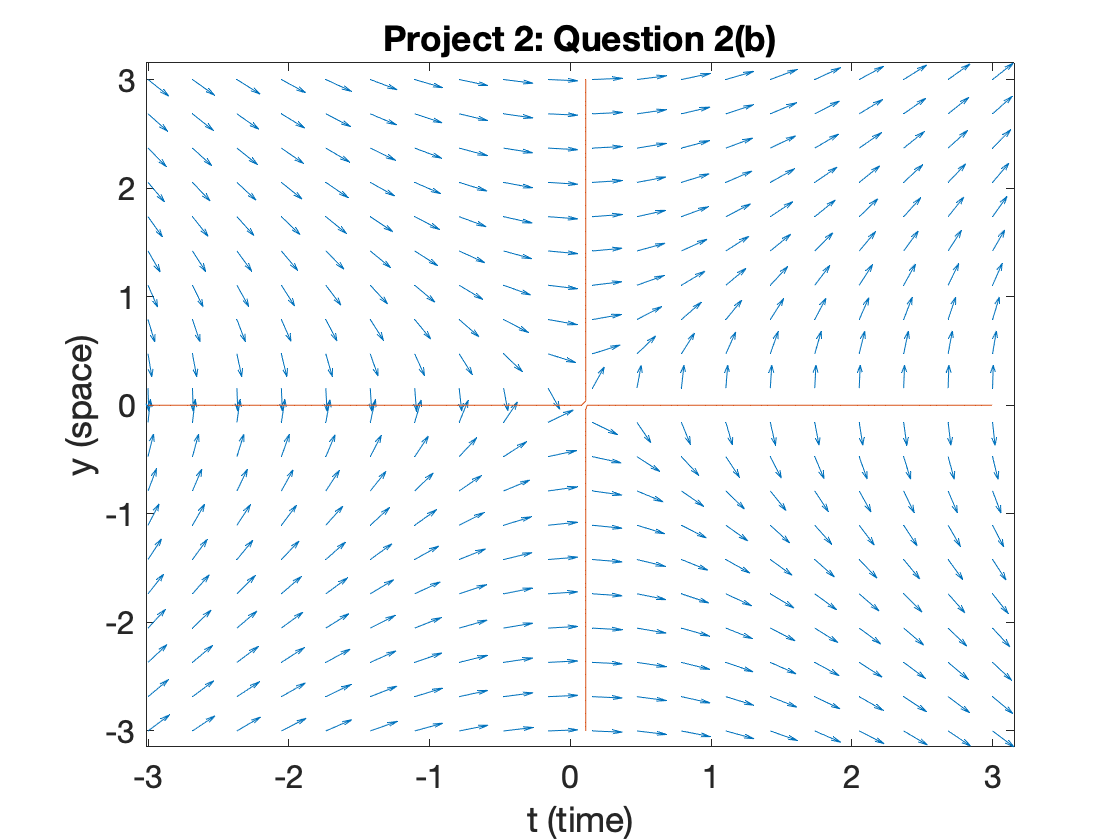

% code goes here
clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure

% define rate function using componentwise arithmetic
f = @(y,t) (3.*t.*exp(2))./(3.*y.*exp(2)-2);

% define grid for direction field
[T,Y] = meshgrid(linspace(-3,3,20),linspace(-3,3,20));

% if you want to see what meshgrid is doing
%figure;
%plot(T,P,'o')

% calculate slope (p'(t)) at each point in our grid
F = f(Y, T);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(f,[-3 3 -3 3])

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Project 2: Question 2(b)')

**(c)**

[Typeset Mathematical Work Here]

**(d)**

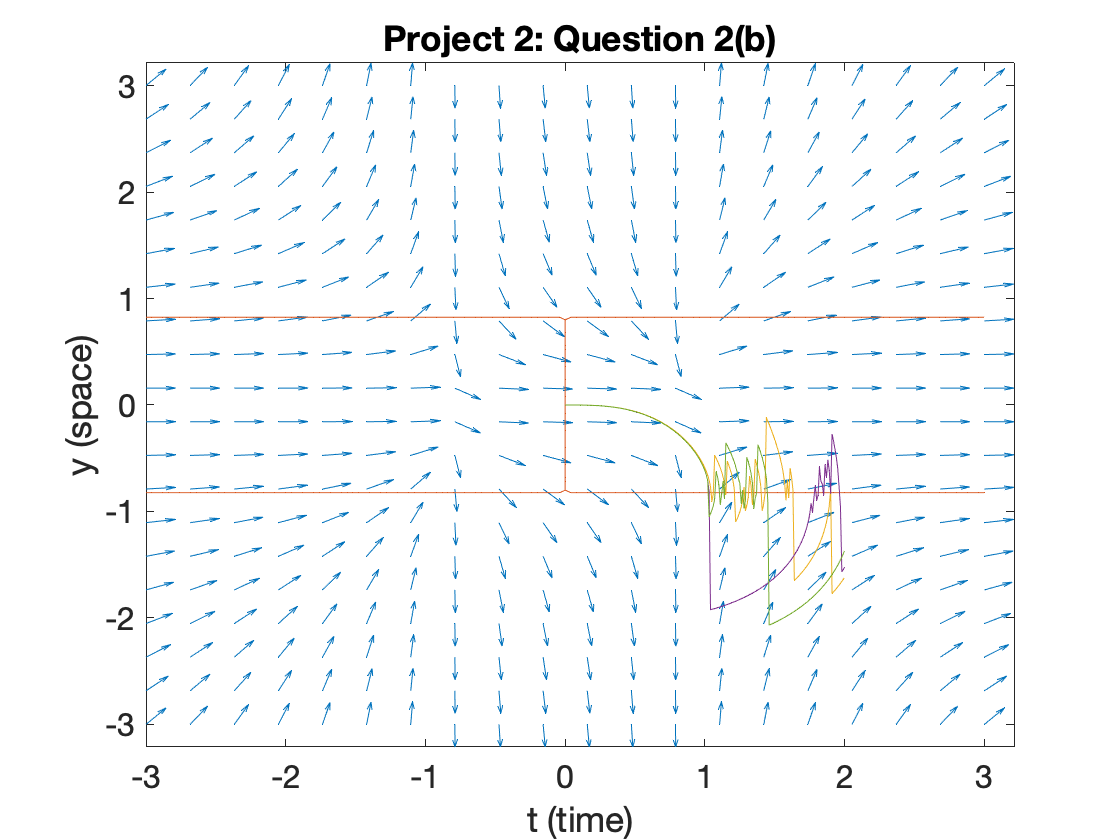

% code goes here
clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure

% define rate function using componentwise arithmetic
f = @(t,y) (3.*t.^2)./(3.*y.^2-2);

% define grid for direction field
[T,Y] = meshgrid(linspace(-3,3,20),linspace(-3,3,20));

% if you want to see what meshgrid is doing
%figure;
%plot(T,P,'o')

% calculate slope (p'(t)) at each point in our grid
F = f(Y, T);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

t = linspace(0,2) ;
h = 0.01;
[t_arr, y_arr] = myEuler(0, 0, f, 2/h, h);
[t_arr_imp, y_arr_imp] = myImprovedEuler(0, f, 2/h, h);
[t_arr_rk, y_arr_rk] = myRK4(0, f, 2/h, h);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(f,[-3 3 -3 3])
plot(t_arr, y_arr)
plot(t_arr_imp, y_arr_imp)
plot(t_arr_rk, y_arr_rk)

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Project 2: Question 2(b)')

**(e)**

[Typeset Discussion Here]

**(f)**

Now for $y\left(0\right)=1$. 

% code goes here 


**(g)**

[Typset summary paragraph here]

## Problem 3

**(a)**

The Euler approximation as derived in class reads $\hat{y}_{n+1} = \hat{y}_n + h f(t_n, \hat{y}_n)$. This was derived from the first order Taylor approximation. If we were to continue use an additional term of the Taylor series, we can truncate after the quadratic term to get a different Euler approximation: 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h\;f\left(t_n ,\hat{y} {\;}_n \right)+\frac{h^2 }{2}\;f^{\prime } \left(t_n \ldotp \hat{y} {\;}_n \right)$, 

where $(t - t_n) = h$ and $y'(t_n) = f(t_n, \hat{y}_n)$. 

**(b)**

In our specific problem, $y'(t) = f(t_n, \hat{y}_n) = -2ty^2$. Therefore, we can rewrite the general expression in (a) as 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +-2h\;t\;{\hat{y} }_n^2 +\frac{h^2 }{2}\left(-2{\hat{y} }_n^2 \right)$. 

This simplifies to


$$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n -2\;h\;t\;\hat{y} {\;}_n^2 -h^2 \hat{y} {\;}_{n\ldotp }^2$$


Therefore the quadratic-truncated Euler approximation is 


$$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n -\left(2t-h\right)h{\hat{y} }_n^2 \ldotp$$


**(c)**

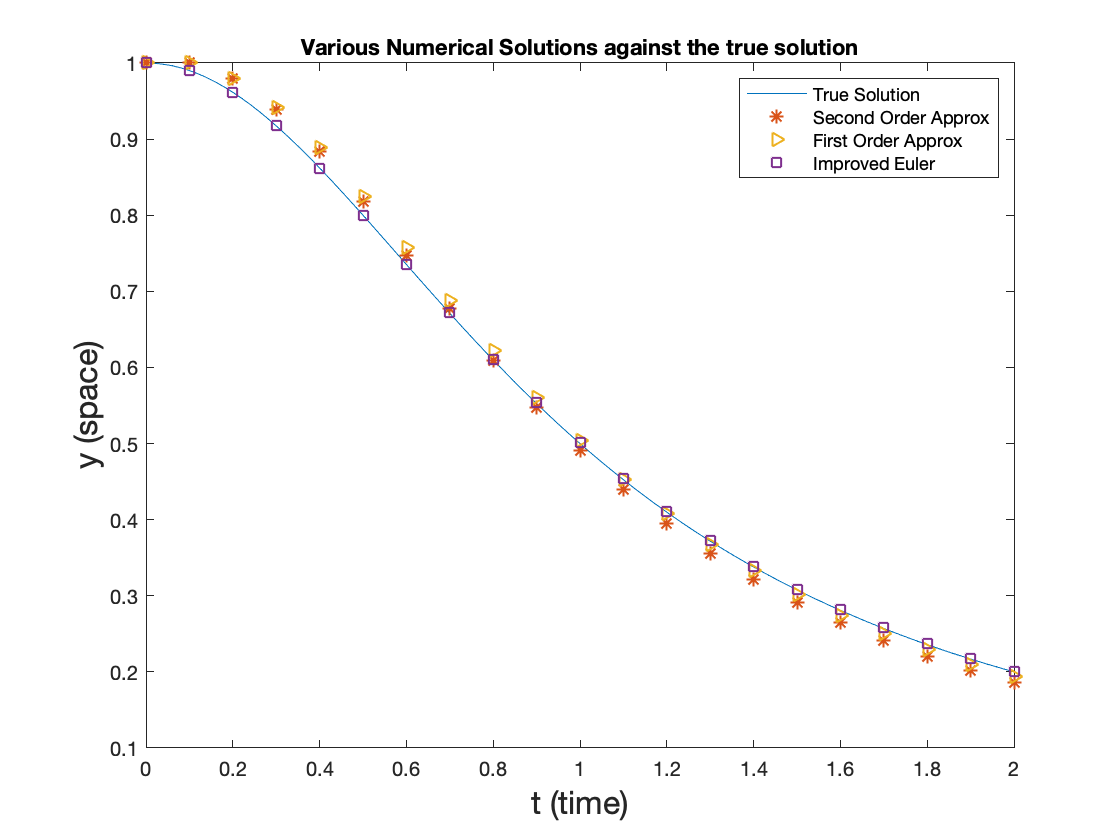

f = @(t,y) -2.*t.*y^2;
h = 0.1 ;
[t_2, yapprox_2] = secondEuler(1, 0, f, 2/h, h) ;

% code from problem 1 here: 
f = @(t, y) -2.*t.*y.^2;
soln1 = @(t) 1./(t.^2 + 1); 
t = linspace(0,2) ;
h = 0.1;

[t_arr, y_arr] = myEuler(1, 0, f, 2/h, h); 
[t_arr_imp, y_arr_imp] = myImprovedEuler(1, f, 2/h, h);

figure
plot(linspace(0,2), soln1(linspace(0,2)))
hold on
scatter(t_2, yapprox_2, "Marker", "*", "LineWidth", 1)
scatter(t_arr, y_arr, "Marker", ">", "LineWidth",1)
scatter(t_arr_imp, y_arr_imp, "Marker", "square", "LineWidth",1)
legend("True Solution", "Second Order Approx", "First Order Approx", "Improved Euler")
xlabel("t (time)", "FontSize",16)
ylabel("y (space)", "FontSize",16)
title("Various Numerical Solutions against the true solution")


% Check convergence
% global error: 
error_e2 = max(abs(soln1(linspace(0,2, 2/h+1)) - yapprox_2.'))

error_e2 = 0.0213

h = h/2

h = 0.0500

[t_2, yapprox_2_1] = secondEuler(1, 0, f, 2/h, h) ;
error_e2_1 = max(abs(soln1(linspace(0,2, 2/h+1)) - yapprox_2_1.'));
conv_euler2 = log2(error_e2/error_e2_1)

conv_euler2 = 1.0815

From this calculation we can determine that $p \approx 1$. Therefore, (**ask about this**) 

**(d)**

[Typeset Discussion Here]

## Problem 4

Climate change is becoming an increasingly important concern in our world right now, as the increase in global temperatures could have long-term, irreversible effects on our weather patterns and temperatures. Although fluctations in temeprature are natural, human activities like burning fossil fuels have caused for an overabundance of greenhouse gases in the atmosphere that can lead to disasterous effects on our global climate. It is important to model these changes in temperature to understand how the temperature changes as a function of the current temperature and efforts of the government to regulate emissions. 

Many experts predict that an increase in $2^o$C increase in temperature will cause the global temperature to depart from a current state of equilibrium and cause a positive feedback loop that results in a new equilibirum $6^{o}$ C higher than the current equilibrium. This would be a significant change and be disastrous for the species and climates on Earth. 

To model this, we have developed a differential equation that demonstrates the relationship between the rate of temperature change $dT/dt$, the current temperature $T$, and the impact of government regulation on the temperature $k$.  This variables have been found by experts to have the relationship

$\frac{\textrm{dT}}{\textrm{dt}}=-\frac{1}{10}\left(T-20\right)\left(T-22\right)\left(T-26\right)-k$,

where the $-1/10$ prefactor is a proportionality constant between the temperature and the rate of temperature change. The $k$ is subtracted from the temperature term based on the assumption that an increase in government regulation decreases the rate of temperature change. In other words, an increase in regulation should work to reverse an increase in temperature. In this form, one can also easily see the equilibrium solutions. It is assumed that the current equilibirum is at $T = 20^{o}$ C, but a $2^{o}$ temperature change will begin a positive feedback loop such that there is a new equilibrium temperature at $26^{o}$ C. At these points the rate of temperature change is constant unless there is an impact due to government regulations.

**(i) Baseline Figure**

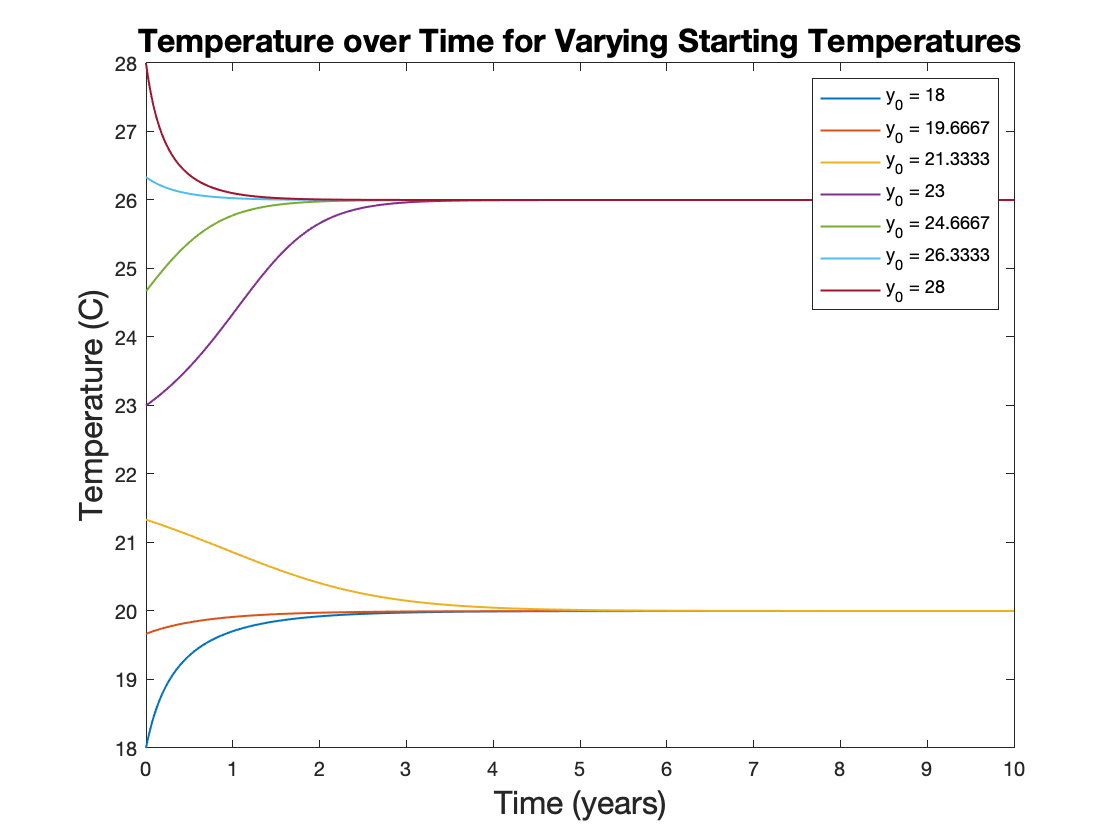

% code goes here: RK4 method 

% Differential equation for the model
f = @(t, T) -(1/10) * (T-20).*(T-22).*(T-26) ;
h = 0.01;
y0 = linspace(18, 28, 7) ;
figure 
for y = 1:length(y0) 
    [t_arr_rk, y_arr_rk] = myRK4(y0(y), f, 10/h, h);
    plot(t_arr_rk, y_arr_rk, "LineWidth",1)
    hold on 
end
legend(strcat("y_0 = ", num2str(y0(1))), strcat("y_0 = ", num2str(y0(2))), strcat("y_0 = ", num2str(y0(3))), strcat("y_0 = ", num2str(y0(4))), strcat("y_0 = ", num2str(y0(5))), strcat("y_0 = ", num2str(y0(6))),strcat("y_0 = ", num2str(y0(7))))
xlabel("Time (years)", "FontSize",16)
ylabel("Temperature (C)", "FontSize",16)
title("Temperature over Time for Varying Starting Temperatures", "FontSize",16)

**(ii) Increased Regulation Figure**

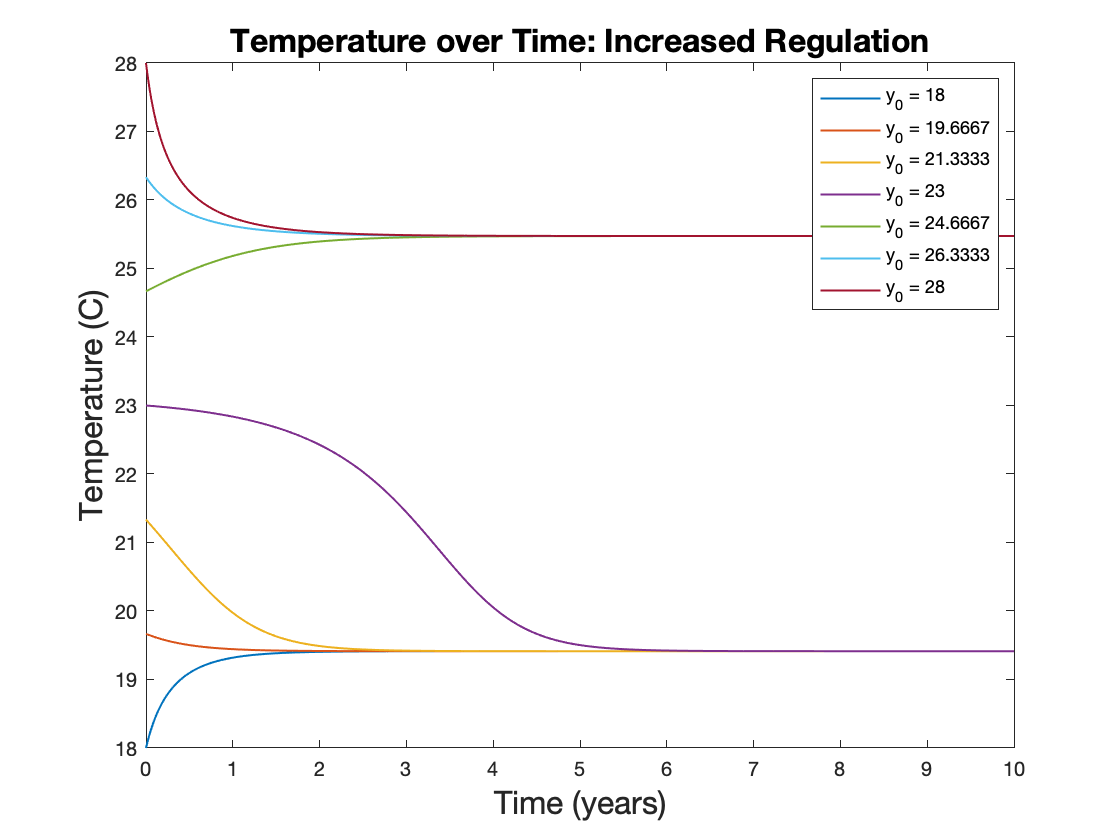

% code goes here
% For increased regulation, I defined a new function below: myRK4_2 that
% has an input k parameter 
f = @(t, T, k) -(1/10) * (T-20).*(T-22).*(T-26)-k ;
h = 0.01;
k = 1;
y0 = linspace(18, 28, 7) ;
figure 
for y = 1:length(y0) 
    [t_arr_rk, y_arr_rk] = myRK4_2(y0(y), f, 10/h, h, k);
    plot(t_arr_rk, y_arr_rk, "LineWidth",1)
    hold on 
end
legend(strcat("y_0 = ", num2str(y0(1))), strcat("y_0 = ", num2str(y0(2))), strcat("y_0 = ", num2str(y0(3))), strcat("y_0 = ", num2str(y0(4))), strcat("y_0 = ", num2str(y0(5))), strcat("y_0 = ", num2str(y0(6))),strcat("y_0 = ", num2str(y0(7))))
xlabel("Time (years)", "FontSize",16)
ylabel("Temperature (C)", "FontSize",16)
title("Temperature over Time: Increased Regulation", "FontSize",16)

[Typeset Summary Paragraph Here]

**(i) Decreased Regulation Figure**

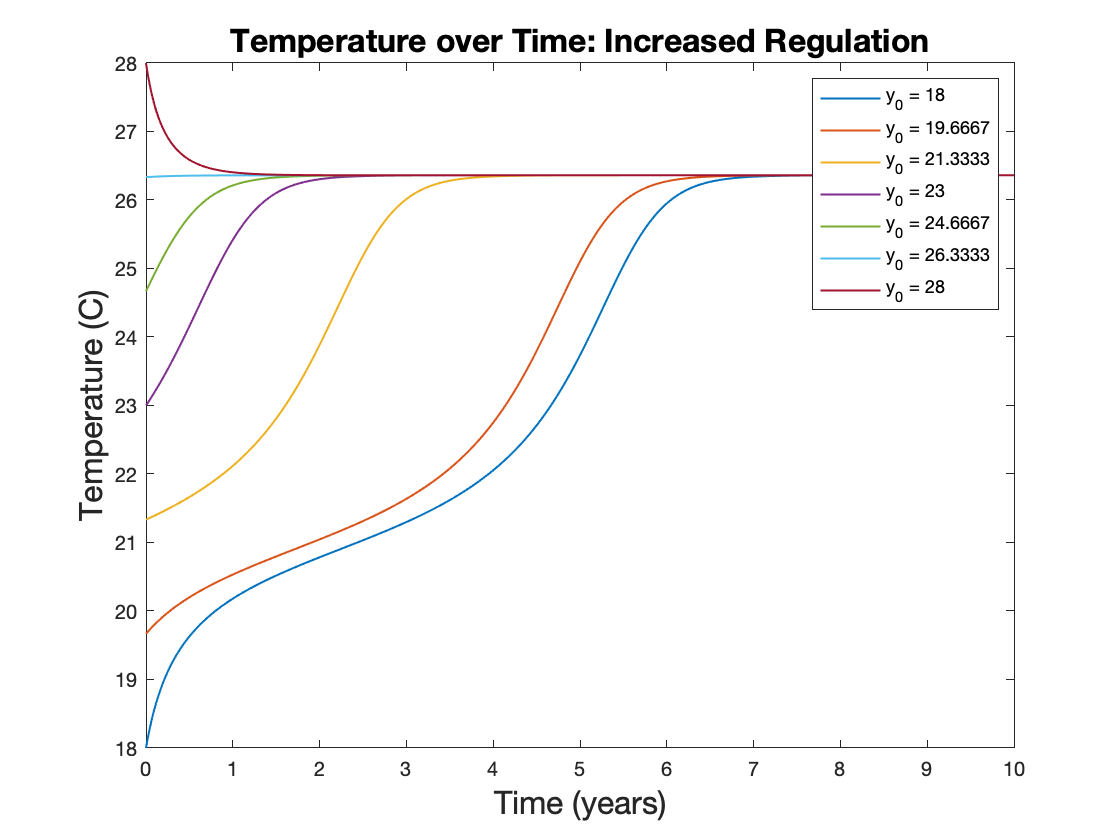

% code goes here
% For increased regulation, I defined a new function below: myRK4_2 that
% has an input k parameter 
f = @(t, T, k) -(1/10) * (T-20).*(T-22).*(T-26)-k ;
h = 0.01;
k = -1;
y0 = linspace(18, 28, 7) ;
figure 
for y = 1:length(y0) 
    [t_arr_rk, y_arr_rk] = myRK4_2(y0(y), f, 10/h, h, k);
    plot(t_arr_rk, y_arr_rk, "LineWidth",1)
    hold on 
end
legend(strcat("y_0 = ", num2str(y0(1))), strcat("y_0 = ", num2str(y0(2))), strcat("y_0 = ", num2str(y0(3))), strcat("y_0 = ", num2str(y0(4))), strcat("y_0 = ", num2str(y0(5))), strcat("y_0 = ", num2str(y0(6))),strcat("y_0 = ", num2str(y0(7))))
xlabel("Time (years)", "FontSize",16)
ylabel("Temperature (C)", "FontSize",16)
title("Temperature over Time: Increased Regulation", "FontSize",16)

[Typeset Summary Paragraph Here]

**"How do you know that your approximated solutions are even accurate?"**

[Typeset ResponseHere]

## Functions

Function for 3c: 

function [t, yapprox] = secondEuler(y0, t0, f, N, h)
 yapprox = NaN(N+1,1); 
 yapprox(1) = y0;
 % time vector
 t = t0:h:h*N;
 for i = 1:N
    yapprox(i+1)=yapprox(i) + h*f(t(i),yapprox(i)) +(h^2)/2*f(t(i),yapprox(i));
 end 
end


%% calculates an approximation to the differential equation y' = f(t,y) y(0) = y0 using RK4 method
% y0 is initial y value
% f is the function handle for the RHS of the diff eq
% N is the total number of steps
% h is the step size
function [t, yapprox] = myRK4_2(y0,f,N,h,k)
% set up empty vector to hold approximation
yapprox = NaN(N+1,1); 
 yapprox(1) = y0;
 % time vector
 t = 0:h:h*N;
 % loop over each step
 for i = 1:N
     % quadrature calculations
     K1 = f(t(i),yapprox(i),k);    %     f(tn, yn)
     yhat = yapprox(i)+(h/2)*K1; %     yn + h/2 K1
     K2 = f( t(i)+h/2, yhat,k);  %       f( tn+h/2, yn + h/2 K1)
     yhat2 = yapprox(i)+ (h/2)*K2; %   yn + h/2 K2
     K3 = f(t(i)+h/2, yhat2,k);  %       f(tn + h/2, yn + h/2 K2 
     K4 = f(t(i)+h, yapprox(i)+ h*K3, k);%f(tn+h, yn + h K3) 
     % approximation 
     yapprox(i+1) = yapprox(i) + (h/6)*(K1 + 2*K2 + 2*K3 + K4);
 end
end

## Honor Code

I have neither given or recieved unauthorized aid on this assignment.  

[Upload an image of your signature here]